# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 장재은**

**학번**** : 201911689**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

xn = [1, 2, 2, 1];
N = 4;
Xk = dft(xn,N);
mag_Xk = abs(Xk); 
pha_Xk = angle(Xk)*180/pi;

mag_Xk

mag_Xk =     6.0000    2.8284    2.0000    2.8284


pha_Xk

pha_Xk =          0  135.0000 -180.0000 -135.0000


Xk = idft(xn,N);
mag_Xk = abs(Xk); 
pha_Xk = angle(Xk)*180/pi;

mag_Xk

mag_Xk =     1.5000    0.7071    0.5000    0.7071


pha_Xk

pha_Xk =          0 -135.0000  180.0000  135.0000


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

xn = [1,2,2,1, zeros(1,12)];
N = 16;
X = dft(xn,N);
mag_Xk = abs(X); 
pha_Xk = angle(X)*180/pi;

mag_Xk

mag_Xk =   120.0000   41.0066   20.9050   14.3996   11.3137    9.6215    8.6591    8.1567    8.0000    8.1567    8.6591    9.6215   11.3137   14.3996   20.9050   41.0066


pha_Xk

pha_Xk =          0  101.2500  112.5000  123.7500  135.0000  146.2500  157.5000  168.7500  180.0000 -168.7500 -157.5000 -146.2500 -135.0000 -123.7500 -112.5000 -101.2500


X = idft(xn,N);
mag_Xk = abs(X); 
pha_Xk = angle(X)*180/pi;

mag_Xk

mag_Xk =     7.5000    2.5629    1.3066    0.9000    0.7071    0.6013    0.5412    0.5098    0.5000    0.5098    0.5412    0.6013    0.7071    0.9000    1.3066    2.5629


pha_Xk

pha_Xk =          0 -101.2500 -112.5000 -123.7500 -135.0000 -146.2500 -157.5000 -168.7500 -180.0000  168.7500  157.5000  146.2500  135.0000  123.7500  112.5000  101.2500


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

xn = [4, 1, -1, 1];
N = 4;
Xk = dfs(xn,N)

Xk =    6.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 - 0.0000i  -2.0000 - 2.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

xn = [1, 0, -1, -1, 0];
N = 5;
Xk = dfs(xn,N)

Xk =   10.0000 + 0.0000i  -2.5000 + 3.4410i  -2.5000 + 0.8123i  -2.5000 - 0.8123i  -2.5000 - 3.4410i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\mathrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \mathrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

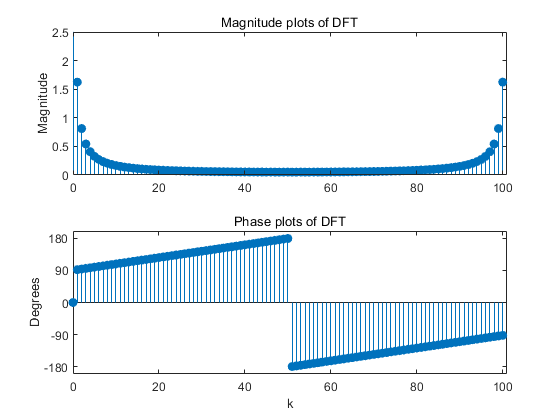

n = 0:100; xn = sinc((n-50)/2).^2; N = length(xn); 
Xk = dft(xn,N); k = 0:N-1; 
mag_Xk = abs(Xk); 
pha_Xk = angle(Xk)*180/pi; 
zei = find(mag_Xk < 0.00001); 
pha_Xk(zei) = zeros(1,length(zei));


subplot(2,1,1); 
H_s1 = stem(k,mag_Xk,"filled");

set(gca,'XTick',[0:20:N]);
axis([0,N,0,2.5]);
set(gca,'YTick',[0:0.5:2.5]); 

ylabel('Magnitude');
title('Magnitude plots of DFT');


subplot(2,1,2); 
H_s2 = stem(k,pha_Xk,'filled'); 

set(gca,'XTick',[0:20:N]); 
axis([0,N,-200,200])
set(gca,'YTick',[-180;-90;0;90;180]);

xlabel('k'); ylabel('Degrees');
title('Phase plots of DFT'); 

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

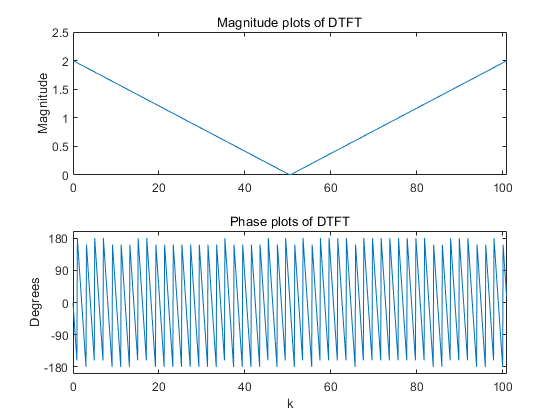

[X,w] = freqz(xn,1,1000,'whole'); 
mag_X = abs(X); pha_X = angle(X)*180/pi; 
Dw = (2*pi)/N; 

subplot(2,1,1); plot(w/Dw,mag_X);
set(gca,'XTick',[0:20:N]);
axis([0,N,0,2.5]);
set(gca,'YTick',[0:0.5:2.5]); 
ylabel('Magnitude');
title('Magnitude plots of DTFT');

subplot(2,1,2); plot(w/Dw,pha_X);
set(gca,'XTick',[0:20:N]); 
axis([0,N,-200,200])
set(gca,'YTick',[-180;-90;0;90;180]);
xlabel('k'); ylabel('Degrees');
title('Phase plots of DTFT'); 

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

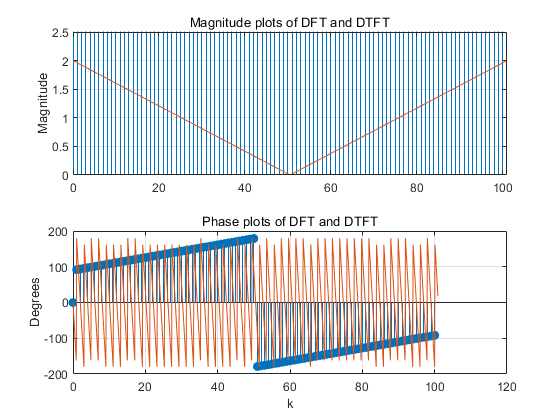

subplot(2,1,1); 
H_s1 = stem(k,mag_Xk,'filled');

set(gca,'XTick',[0:20:N]); axis([0,N,0,2.5])
set(gca,'YTick',[0:0.5:2.5]); 

ylabel('Magnitude');
title('Magnitude plots of DFT and DTFT'); hold on

subplot(2,1,2); 
H_s2 = stem(k,pha_Xk,'filled'); 
xlabel('k'); ylabel('Degrees');
title('Phase plots of DFT and DTFT'); hold on
subplot(2,1,1); plot(w/Dw,mag_X); grid
hold off
subplot(2,1,2); plot(w/Dw,pha_X); grid
hold off

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

재구성할 수 있다. 재구성에 필요한 DTFT 보간 공식은 다음과 같다.  

$X\left(e^{j\omega } \right)=\sum_{k=\;0}^{N-1} X\left(k\right)\phi \left(\omega -\frac{2\pi k}{N}\right)$,  $\phi \left(\omega \right)=\frac{\sin \left(\frac{\omega N}{2}\right)}{\mathrm{Nsin}\left(\frac{\omega }{2}\right)}e^{-j\omega \left(\frac{N-1}{2}\right)}$


function [Xk] = dfs(xn, N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = n * WNnk;
end

function [Xk] = dft(xn, N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = n * WNnk;
end

function [Xk] = idft(xn, N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
Xk = (n * WNnk)/N;
end